# Part I: Introduction to Battery Modelling with BattMo

**Dr. Sridevi Krishnamurthi **and** Dr. Simon Clark, ***SINTEF AS, Battery Technology, Trondheim, Norway*

This guide provides an introductory resource for readers who would like to learn about lithium-ion batteries, battery modelling, or both! Starting from the basics of how a Li-ion battery works, we go step-by-step, introducing new modelling concepts at each level. After completing this guide, readers should have a working knowledge of Li-ion battery design principles and be able to simulate a variety of designs under different conditions. 

The guide is divided into three parts:

- **Part I: Introduction to Battery Modelling with BattMo** introduces the basic concepts of Li-ion battery design and operation. This part introduces the types of simulations that BattMo can perform and provides some examples demonstrating simple design modifications

- **Part II: The DFN Model overview** explains how the model operates and examines how the model parameters influence capacities.

- **Part III: Engineering **use cases delves into the cell design problems such as electrode balancing, rate capability analysis

- **Part IV: Ageing mechanisms and cell engineering **discusses the SEI and Lithium plating issues as part of the ageing mechanism, we also intoduce P4D models for dealing with complex geometries.

Rechargeable Li-ion batteries have transformed our lives. With the current focus on electrifying the mobility sector and the growing need to support intermittent renewable energy sources, there is much to learn about batteries and the materials that make them. The goal is to develop batteries with higher energy density and improved safety, manufactured in a sustainable manner.

BattMo is a powerful tool for conducting battery simulations, aiding in the understanding and optimization of battery performance. It utilizes continuum scale PXD (pseudo-X-dimensional) simulations based on the Doyle-Fuller-Newman (DFN) model. By providing material and design parameters for the various components of the battery, BattMo can simulate how key quantities like voltage, current, concentration, and temperature change in the battery as it is operated. When simulated over many charge-discharge cycles, BattMo can also predict capacity losses that occur due to degradation. It supports simulations from simple 1D grids to complex multi-layer pouch cells and jelly rolls, incorporating thermal effects and degradation mechanisms. Its modular design facilitates easy switching between different cell chemistries, making BattMo versatile for applications in battery research and development. 

For a detailed overview of the modelling approach and the DFN model, please refer to **Part II **of this modelling guide.

## **1. Lithium-Ion Battery Basics**

Let's begin by exploring some lithium-ion (Li-ion) battery basics. The battery cell consists of three main components: **a negative electrode**, **a positive electrode**, and **an electrolyte**. 

Each electrode contains an **active material** that stores energy by incorporating lithium into its chemical structure through an electrochemical reaction like intercalation or alloying. There are a variety of materials that could be used for active materials, but typical Li-ion batteries use graphite for the negative electrode and a lithiated transition metal oxide for the positive electrode. The active materials act as a stable host structure for storing Li-ions. You can think of them like shelves and the Li-ions like boxes. Boxes can be moved from one shelf to another, but the shelf itself remains stable. 

The electrodes are linked by an electrolyte that serves as a type of "highway" for transporting Li+ ions, and it typically consists of a lithium salt like LiPF6 dissolved in a carbonate-based solvent. The electrolyte must support the fast transport of ions, while also blocking the transport of electrons. The electronically insulating nature of the electrolyte forces the electrons through an external circuit, providing electrical energy to connected devices. We will look at the exact types of materials used for these components later. 

A schematic overview of this process for a graphite - lithium cobalt oxide (LCO) cell is shown in **Figure 1**. The basic operating principle of the Li-ion battery is sometimes refered to as a "rocking-chair" mechanism, because the rock back-and-forth between the positive and negative electrodes. When the Li-ion battery cell is charged, an externally applied voltage drives Li+ to de-intercalate from the positive electrode into the electrolyte where they are transported via diffusion-migration to the negative electrode. Electrons are released from the oxidation of cobalt in the positive electrode (Co3+ -> Co4+), travel through the external circuit, and recombine with lithium in the negative electrode [1]. When the Li-ion battery cell is discharged, the process is reversed. Driven by the change in the Gibbs Free Energy, Li is oxidized in the negative electrode and is transported across the electrolyte where it combines with electrons from the external circuit and is intercalated back into the positive electrode active material. 

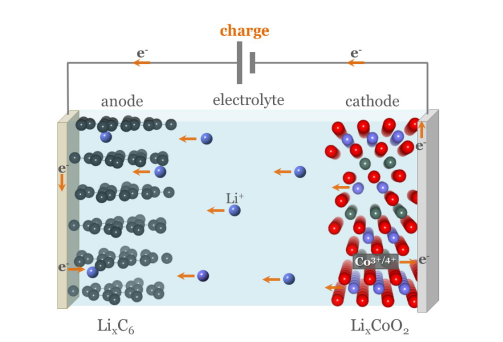

**Figure 1: A schematic representation of a typical Li-ion cell during charging. ***The Li-ion cell is a stack of a negative electrode, a positive electrode, and a Li+ containing electrolyte. The Li-ion cell works on the principle of intercalation, where Li+ ions are inserted into vacant sites in the electrode active materials. While a variety of active materials could be used for the electrodes, typical Li-ion batteries use graphite for the negative electrode and a lithiated transition metal oxide like LiCoO2 for the positive electrode [1]. *

### **1.1 Cell Components **

Lithium-ion battery electrodes are porous composite structures that consist of a mixture of **active material**, **binder**, and **conducting additives** applied as a coating on a foil **current collector**. When the cell is assembled, the electrolyte is injected into the device and fills up the pores in the electrode, creating interfaces with the active materials where the electrochemical reactions can take place.

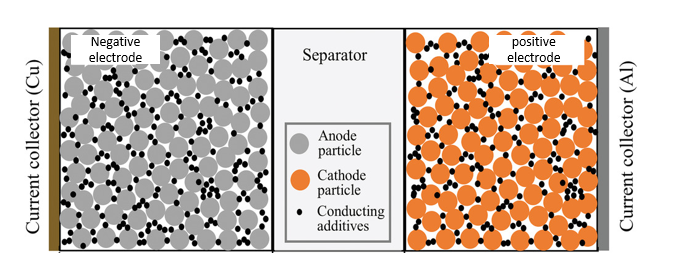

**Figure 2:** **Cross-sectional layout of a LIB with two porous electrodes and a porous separator.** *The active materials in the anode (negative electrode) and cathode (positive electrode) are simplified to spherical particles with gray and orange colors. The conducting additives are simplified to black small particles [6].*

**Positive Electrode**

Active materials for positive electrodes in Li-ion batteries are lithium transition metal oxides, which come in a variety of different compositions and crystal structures. The most common oxides NMC (lithium nickel manganese cobalt oxide), LFP (lithium iron phosphate), LMO (Llithium manganese oxide), LNO (lithium nickel oxide) LCO (lithium cobalt oxide) and NCA (lithium nickel cobalt aluminium oxide). Because these materials differ in energy density, cycling stability, commercial availability, and environmental impact, selecting the appropriate one for each application is crucial.  For a thorough review of positive electrode materials, the reader can refer [here](https://www.nature.com/articles/s41467-020-15355-0).

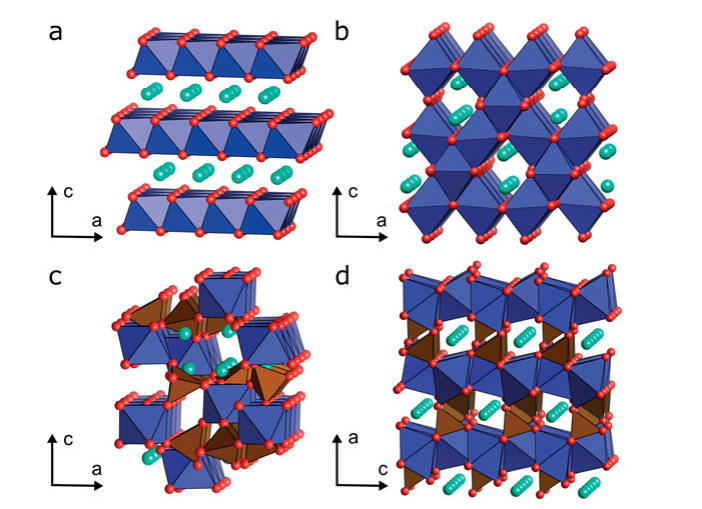

**Fig. 3: **.**Crystal structures of transition metal oxides used as positive electrode active materials:** *(a) layered LiMO2 (M = Co, Ni, Mn, etc.), (b) spinel LiMn2O4, (c) NASICON-type Li3Fe2(PO4)3, and (d) olivine LiFePO4. The transition metal octahedra, MO6, are represented in blue, while the polyanion tetrahedra, XO4, are represented in brown. Li-ions are shown in turquoise[7]. *

**Negative Electrode**

Graphite is the most common active material for the negative electrode in Li-ion cells, although alternative materials like silicon (Si) and lithium titanate (LTO) are used for some specialty applications. Early versions of rechargeable lithium batteries used lithium metal as the negative electrode active material due to its high specific capacity. However, ltihium metal can form dendritic or needle-like structures during charging, which can cause to safety-critical internal short-circuits. Nonetheless, research and development of lithium metal systems with advanced electrolytes continues as a way to increase the specific energy / energy density of rechargeable batteries. For a review on on carbon based negative electrode materials, one can refer [here](https://www.sciencedirect.com/science/article/pii/S2352152X23001135).

**Electrolyte**

The electrolyte serves as the medium for Li-ion conduction and can be either solid or liquid. Liquid electrolytes typically consist of lithium salts dissolved in an organic solvent, with common examples being LiPF6, LiBF4, and LiClO4. Commonly used solvents are ethylene carbonate, dimethyl carbonate, and diethyl carbonate. A good electrolyte, whether solid or liquid must possess high ionic conductivity, low electronic conductivity, support high voltages, and remain stable across a wide temperature range. For a review on liquid electrolytes, one can refer [here](https://onlinelibrary.wiley.com/doi/full/10.1002/smll.202205315).

**Separator**

The separator is typically made from polymer materials such as polyethylene (PE) or polypropylene (PP). It serves as a porous medium allowing lithium ions to move between the positive and negative electrodes. While the separator itself does not participate in the electrochemical reactions, it can influence the safety, power density, and cycle life of the battery.

### **1.2 Working Principle**

During charging, lithium ions (Li+) are deintercalated from the positive electrode (in this example, NMC) and migrate to the negative electrode (in this example, graphite) through the electrolyte. Concurrently, electrons are driven through the external circuit from NMC to graphite. During discharging, the reverse process occurs: lithium ions migrate back from the negative electrode (graphite) to the positive electrode (NMC) through the electrolyte, while electrons flow from graphite to NMC through the external circuit. 

 **At the positive electrode: **

$\[
\text{Li}\text{[NiMnCo]O}_2 \overset{\text{charge}}{\underset{\text{discharge}}{\rightleftharpoons}} \text{Li}_{(1-x)}\text{[NiMnCo]O}_2 + x\text{Li}^{+} + x\text{e}^{-}
\]
$ (1.1)

**At the negative electrode:**

$% Anode Reaction (Discharge)

\[
\text{C}_6 + y\text{Li}^{+} + \text{e}^{-} \overset{\text{charge}}{\underset{\text{discharge}}{\rightleftharpoons}}\text{Li}_y\text{C}_6
\]$  (1.2)

**The overall cell reaction:**

$% Overall Cell Reaction (Discharge)
\[
 \text{[LiNiMnCo]O}_2 + \text{C}_6  \overset{\text{charge}}{\underset{\text{discharge}}{\rightleftharpoons}}  + \text{Li}_{1-x}\text{[NiMnCo]O}_2+  \text{Li}_y\text{C}_6
\]

$ (1.3)

The system is at its lowest energy when the Li-ions are in the positive electrode, during discharge, the Li ions migrate from the negative electrode to the positive electrode and the potential difference is released as energy. A detailed thermodynamic description will be presented in part 2 of the guide.

### 1.3 Battery Properties 

A good battery should posess high energy density, ensuring it can store a significant amount of energy relative to its size and weight. Additionally, it should maintain a long cycle life, allowing it to endure numerous charge and discharge cycles without significant degradation. Minimal energy loss during these cycles is crucial, ensuring efficient energy usage and prolonged operational efficiency. 

Let's delve into essential terms and parameters crucial for understanding batteries and their simulation in BattMo. These help in evaluating and comparing battery performance and characteristics.

**Definitions:**

- [Lower](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_534dd59c_904c_45d9_8550_ae9d2eb6bbc9) ([upper](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_6dcd5baf_58cd_43f5_a692_51508e036c88)) voltage limit:The minimum (maximum) allowable voltage. It is this voltage that generally defines the “empty” ("full") state of the battery, this is set as an input parameter in the simulation.The value depends on the cell chemistry.

- [C-Rate](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_e1fd84eb_acdb_4b2c_b90c_e899d552a3ee) (cycling rate): this is the rate at which a battery is discharged in relation to its maximum capacity. Specifically, a 1C rate signifies that the discharge current will exhaust the total battery capacity in 1 hour. The CRate chosen depends on your application, this is set as an input parameter in the simulation

- [State of Charge (SOC %)](https://w3id.org/emmo/domain/battery#battery_17591da0_34ec_41b9_b3c1_3a4446dc6f0a): ratio of the current battery capacity to its maximum capacity, this is set as an input parameter in the simulation

- [Open-Circuit Voltage](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_9c657fdc_b9d3_4964_907c_f9a6e8c5f52b) (OCV): The voltage between the positive electrode and the negative electrode with no external load, to calculate this in BattMo,one can use a very small charge/discharge current, a CRate of C/20. OCV curves are typically plotted as voltage versus state of charge (SOC), the curves depend on the chemistry of the cell.

**Cell Properties:**

- [Capacity](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_791c1915_a791_4450_acd8_7f94764743b5) / Ah: electric charge which a cell or battery can deliver under specified discharge conditions, calculated as a product of discharge current and discharge time. Increasing the CRate decreases the capacity due to increasing internal losses.

- [Nominal Capacity](https://w3id.org/emmo/domain/battery#battery_fb9baf9b_680e_493e_a755_da9bb1fc9fae) / Ah: the rated capacity that is representative of the typical value associated with a cell as stated by the manufacturer

- [Theoretical Capacity](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_b7781ebc_90a7_4f19_997f_aed28dee1b01) / Ah: maximum possible charge, a cell can store, it is a fixed value determined by the amount and type of active material used in the electrodes.

- [Energy](https://w3id.org/emmo/domain/battery#battery_87bb15ff_4fc2_4929_9938_0b31d9166001) / Wh: calculated as the product of capacity and the average discharge voltage when discharged at a specific C-rate,Increasing the CRate decreases the energy.

- [Energy Density](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_4aa1b96e_44a0_4b1a_a0ac_723d0223d80b) / Wh/L: calculated as the energy divided by the volume of the cell

- [Specific Energy](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_5e4490b8_c1dd_4e00_980b_c484e1bf4904) / Wh/kg: calculated as the energy divided by the mass of the cell

- [Round-Trip Efficiency](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_79198264_cdf5_4fc3_8bcf_e5140a52547a): ratio of the energy released during discharge to the energy stored during charge. This parameter indicates how effectively a battery converts stored energy into usable energy.

### **1.4 Operational Protocols**

In BattMo, we set the protocols for the charging and discharging of the cell using the [control model schema](https://battmoteam.github.io/BattMo/controlinput.html#control-models). We discuss the basic protocols here:

- **Constant Current Discharging.** During discharge, a constant current (CC) based on the chosen C-rate is drawn from the cell until the voltage reaches the minimum cut-off voltage (lowerCutoffVoltage) of the cell.

- **Constant Current Constant Voltage Charging. **A Li-ion battery is typically charged using a constant current/constant voltage protocol (CC-CV). This means the battery is initially charged at a constant current until it reaches a maximum voltage (upperCutoffVoltage). Once this voltage is reached, the protocol switches to maintaining a constant voltage between the terminals while the charging current gradually decreases. 

## **2. Modelling with BattMo**

BattMo comes with several default material and cell parameter sets; for more details, refer [here](https://github.com/BattMoTeam/BattMo/tree/main/ParameterData/ParameterSets). Users can also input their own parameterization data. BattMo uses the JSON (JavaScript Object Notation) format to manage input parameters. This allows you to easily save, document, and share complete parameter sets from specific simulations. If you are new to JSON, you can learn more about it [here](https://www.w3schools.com/js/js_json_intro.asp). 

For the rest of this guide, we will use a starter JSON file, [sample_input.json](https://github.com/BattMoTeam/BattMo/blob/main/Examples/JsonDataFiles/sample_input.json) that describes a lithium nickel manganese cobalt oxide (NMC 811) - graphite cell [2] with LiPF6 [3] as the electrolyte, in a 1D cell according to BattMo['s JSON input specification](https://battmoteam.github.io/BattMo/json.html#json-input-specification). 

This sample_input.json file contains all the information needed to run the simulation. These parameters are neatly arranged into structured schemas. Unless otherwise specified, BattMo uses [SI base units](https://www.nist.gov/si-redefinition/definitions-si-base-units) for physical quantities.

**Input schema:**

- A schema for the [**geometry**](https://battmoteam.github.io/BattMo/geometryinput.html#batterygeneratorp2d)**, **contains the dimensions of the whole cell and the different components within the cell.

- A schema for the [**battery cell material parameters**](https://battmoteam.github.io/BattMo/json.html#material-parameters)**, **contains material parameters for the NMC - Graphite cell sourced from the literature.

- A schema for the **initialization of the state of the battery,** specifies the initial state of the battery, including the initial state of charge (SOC).

- A schema for the [**control model**](https://battmoteam.github.io/BattMo/controlinput.html#control-models), defines the charging and discharging protocols,

- A schema for the [**time stepping**](https://battmoteam.github.io/BattMo/json.html#time-stepping-parameters)**,**

- A schema for the [**solver parameters**](https://battmoteam.github.io/BattMo/json.html#time-stepping-parameters)**, **specifies the parameters for the numerical solver used in the simulation.

- A schema for the [**output specification**](https://battmoteam.github.io/BattMo/json.html#output-parameters)

### **2.1 P2D/P3D/P4D Models**

As previously mentioned, BattMo utilizes the DFN model, which can be applied across different grid dimensions, ranging from P2D to P4D. The P2D model simulates battery properties along the thickness direction on a macroscopic scale while neglecting in-plane variations, essentially representing a 1D geometry, hence the term "pseudo-2D."  The equations governing the P2D model will be detailed in the second part of the modelling guide. While the P2D model provides a sufficient approximation in many cases, it cannot capture the full complexity of a real battery cell. To address this, the P3D/P4D models incorporate additional spatial dimensions for higher resolution. However, this increased resolution also results in longer computation times and higher computational demands. 

BattMo offers grid generator functions that create battery geometries ranging from P2D to P4D and configures the grid for calculations according to the specified input dimensions and discretization parameters. For more details, see [here](https://battmoteam.github.io/BattMo/geometryinput.html).

 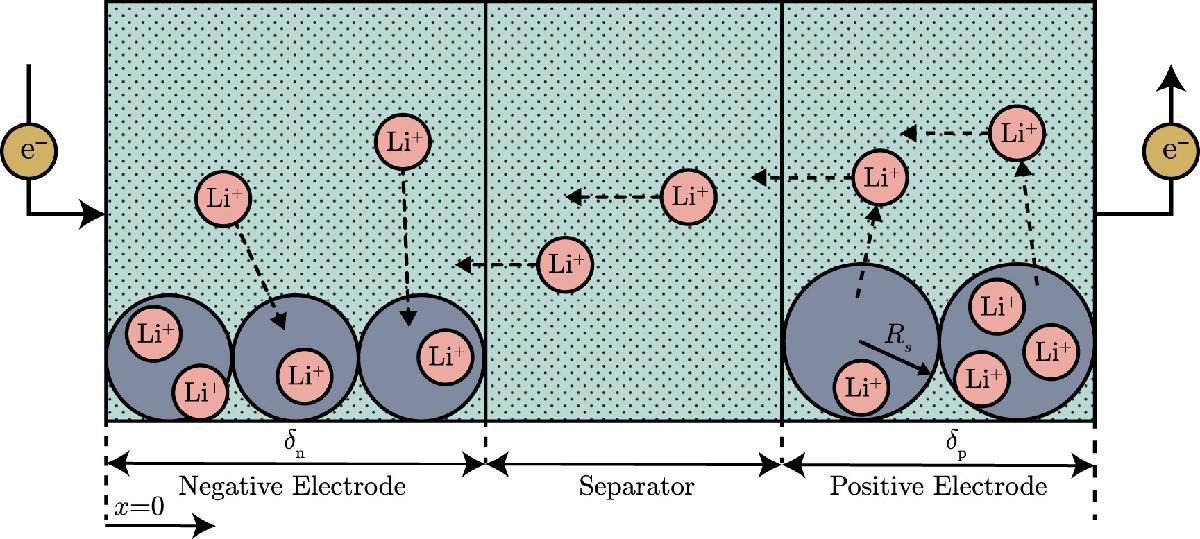

**Figure 4: A schematic representation of the P2D model.** *The cell is divided into three regions: the positive and negative electrodes, depicted as spherical particles, and the electrolyte, which fills the spaces between these particles. The figure illustrates the charging process, showing Li-ions deintercalating from the positive electrode particles and migrating to the negative electrode spheres [5].*

#### **Example 1. Build and Visualize the Battery Grid in 3D**

As the first step in modeling, let’s examine how a battery is represented in BattMo in a 3D grid. There are convenient built-in functions that help in parsing and visualizing data. 

- Load the default sample_input.json file using parseBattmoJson function.

- Merge the default file with a 3D Geometry File with mergeJsonStructs and visualise a 3D battery cell using plotBatteryGrid.

jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
jsonstruct_3d_geometry = parseBattmoJson('Examples/JsonDataFiles/geometry3d.json');
jsonstruct_modified_3d = mergeJsonStructs({jsonstruct_3d_geometry , ...
    jsonstruct_default});

parameter include_current_collectors is assigned twice with different values. we use the value from first jsonstruct.
parameter Geometry.case is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.Coating.thickness is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.Coating.N is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.CurrentCollector.N is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.thickness is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.N is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.CurrentCollector.N is assigned twice with different values. we use the value from first jsonstruct.
parameter Separator.thickness

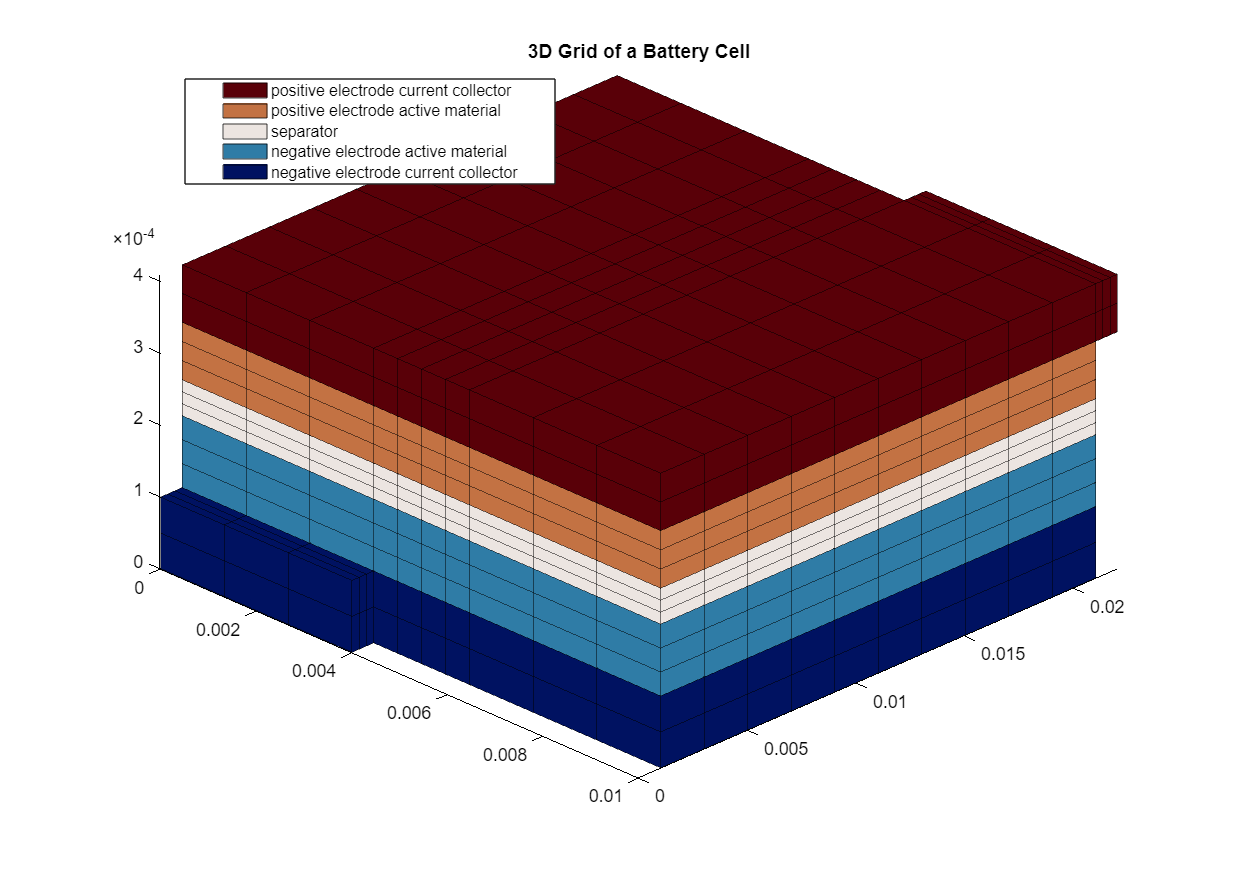

model_3d = setupModelFromJson(jsonstruct_modified_3d);
plotBatteryGrid(model_3d)
axis tight
view(45,45)
set(gca, 'FontSize', 12)
legend('Position', [0.15, 0.8, 0.3, 0.1]);
title('3D Grid of a Battery Cell')

#### **Example 2. Constant Current Discharging of a Gr-NMC Battery Cell in 1D geometry**

Now we are ready to run our first simulation. Refer to the `[sample_input.json](https://github.com/BattMoTeam/BattMo/blob/main/Examples/JsonDataFiles/sample_input.json)` for the exact input values. In summary, we will simulate the constant current (CC) discharge of an NMC-Graphite system, starting from a 100% state of charge (SOC) at a C-rate of 1. For the sake of the tutorial, we will make use of the 1D geometry and run P2D simulations,  Let us visualise this system first,

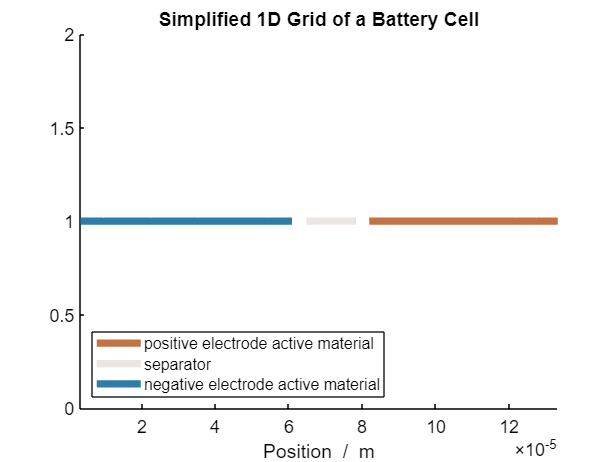

jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
model_1d = setupModelFromJson(jsonstruct_default);

% use the plotBatteryGrid function to show the grid
plotBatteryGrid(model_1d)
axis tight
set(gca, 'FontSize', 12)
xlabel('Position  /  m')
title('Simplified 1D Grid of a Battery Cell')

Before running the actual simulation, the function `computeCellCapacity.m` processes the material parameters for the active materials in the electrodes, along with their mass fractions, to compute the maximum cell capacity (theoretical capacity). Using this capacity, the program sets the discharge current accordingly ($\(\text{capacity} = \frac{1}{\text{C-rate}} \times \text{discharge current}\)$)

*Can we show the maximum cell capacity value, 'cell specification summary'?*  

***>> Simon: Yes, that's a good idea. We should add that. <<***

***>>Sridevi: Will check this ***

For this system, the typical lower and upper cutoff voltages are 2.4 V and 4.1 V, respectively. The simulation stops when the lower cut-off voltage is reached.

jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');% parse the sample_input.json
disp(jsonstruct.Control);% see the default values set in the control policy

         controlPolicy: 'CCDischarge'
                 CRate: 1
    lowerCutoffVoltage: 2.4000
    upperCutoffVoltage: 4.1000
             dIdtLimit: 0.0100
             dEdtLimit: 0.0100
            rampupTime: 0.1000



The simulation can then be executed using the `runBatteryJson` function. 

jsonstruct.TimeStepping.totalTime = (1./jsonstruct.Control.CRate) .* 3600 .* 1.2;
output_dis_NMC = runBatteryJson(jsonstruct); 

Solving timestep 01/45:                     -> 3 Seconds, 375 Milliseconds
Solving timestep 02/45: 3 Seconds, 375 Milliseconds -> 6 Seconds, 750 Milliseconds
Solving timestep 03/45: 6 Seconds, 750 Milliseconds -> 13 Seconds, 500 Milliseconds
Solving timestep 04/45: 13 Seconds, 500 Milliseconds -> 27 Seconds
Solving timestep 05/45: 27 Seconds          -> 54 Seconds
Solving timestep 06/45: 54 Seconds          -> 108 Seconds
Solving timestep 07/45: 108 Seconds         -> 216 Seconds
Solving timestep 08/45: 216 Seconds         -> 324 Seconds
Solving timestep 09/45: 324 Seconds         -> 432 Seconds
Solving timestep 10/45: 432 Seconds         -> 540 Seconds
Solving timestep 11/45: 540 Seconds         -> 648 Seconds
Solving timestep 12/45: 648 Seconds         -> 756 Seconds
Solving timestep 13/45: 756 Seconds         -> 864 Seconds
Solving timestep 14/45: 864 Seconds         -> 972 Seconds
Solving timestep 15/45: 972 Seconds         -> 1080 Seconds
Solving timestep 16/45: 1080 Seconds      

 The output matrix returns among other things the model and the states. The model contains information about the setup of the model and initial conditions, while states contains the results of the simulation at each timestep. The model can also output the energy, energy density and specific energy of the system.

disp(output_dis_NMC);

             model: [1×1 Battery]
       inputparams: [1×1 BatteryInputParams]
          schedule: [1×1 struct]
         initstate: [1×1 struct]
              time: [62×1 double]
                 E: [62×1 double]
                 I: [62×1 double]
            states: {62×1 cell}
            energy: [61×1 double]
     energyDensity: [61×1 double]
    specificEnergy: []



The `plotDashboard` function displays the Li-ion concentration profile in both the solids and electrolytes, as well as the electrode potentials at a specific time step. 

The concentration profiles help understand how efficiently the intercalation (and deintercalation) processes have occurred. They can identify performance issues such as lithium plating or irreversible lithium loss.

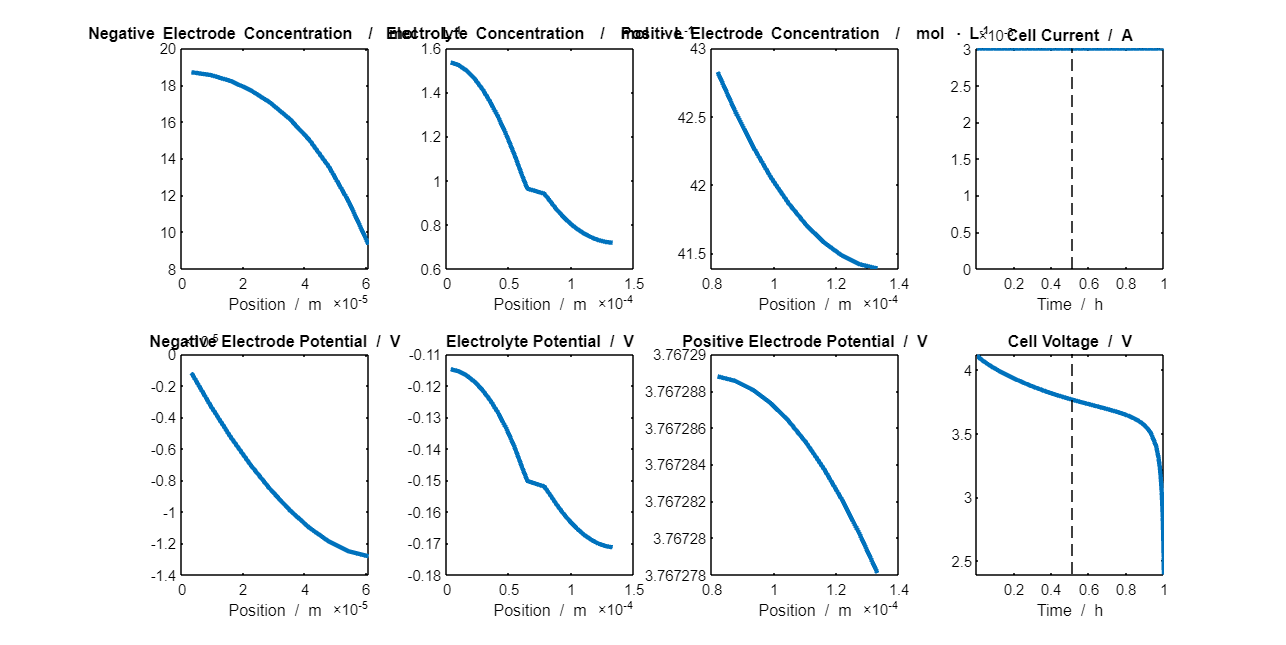

step_number = 23;
plotDashboard(output_dis_NMC.model, output_dis_NMC.states, 'step', step_number); 

#### **Example 3. Post-Processing Voltage Curves**

Let's examine the voltage versus capacity curve, which represents the cell discharge profile. The voltage curve typically exhibits three distinct segments:

- An initial drop, caused by internal resistances and the activation of electrochemical processes.

- A gently sloping or plateau region where the voltage remains relatively stable. A longer plateau region in a battery's discharge profile is beneficial as it signifies that the voltage remains stable with minimal fluctuations across a substantial portion of its capacity, ensuring consistent and efficient energy delivery. The length and voltage of this plateau depend on the cell chemistry.

- A final drop as the cell approaches its capacity limit.

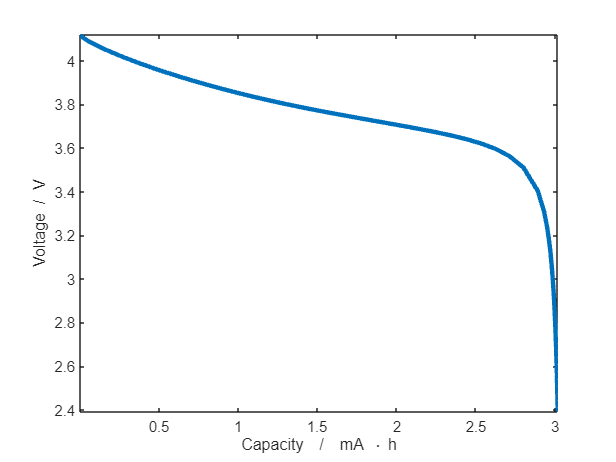

    % Extract the states from the output
    states = output_dis_NMC.states;

    % Extract the time, voltage, and current quantities
    time = cellfun(@(state) state.time, states);
    voltage = cellfun(@(state) state.('Control').E, states);
    current = cellfun(@(state) state.('Control').I, states);

    % Calculate the capacity
    capacity = time .* current;

    % Instantiate an empty figure
    figure()

    % Plot the discharge curve in the figure
    plot((capacity / (hour * milli)), voltage, '-', 'linewidth', 3)

    % Label the axes
    xlabel('Capacity  /  mA \cdot h')
    ylabel('Voltage  /  V')

    % Adjust the axis limits
    axis tight

### **2.2 Influence of structural and material parameters on the capacity**

For a given cell chemistry, the capacity of a cell is constrained by the number of lithium ions that can be safely intercalated and deintercalated from the electrodes. As cells age, they experience irreversible loss of lithium ions, which reduces their capacity over time. We will look at ageing mechanisms in a later chapter. Now, let's examine how material parameters affect cell capacity. One method to increase a cell's capacity, or the amount of energy stored, is by increasing the mass loading, which is the amount of active material per unit area of the electrode. This can be achieved by reducing the number of pores to increase the effective density or by increasing the mass fraction of the coating relative to other components, such as binders and additives. Alternatively, the thickness of the electrode can be increased while maintaining the same ratio of components, thereby adding more active material.

#### **Example 4. Increasing the thickness of the negative electrode / positive electrode**

Please set the electrode type (electrodeType) to be either 'NegativeElectrode' or 'PositiveElectrode' in the code below.

**negative electrode:**

We maintain the NMC positive electrode at a constant thickness while increasing the graphite electrode thickness from 32 micrometers to 72 micrometers to observe its impact on the capacity of our 1D system. Additionally, we switch to the CC-CV protocol, where we first charge the cell with constant current-constant voltage (CC-CV) and then discharge it at constant current. 

We plot the discharge curve and observe that the capacity increases for 32 < 45 < 64 micrometers. However, beyond 64 micrometers, further increasing the thickness has no effect on capacity. This is because the amount of lithium in this scenario is limited by the NMC positive electrode. Although more lithium can initially intercalate into the thicker graphite, beyond a certain thickness, there is no additional lithium available to intercalate into the graphite that can be extracted during discharge. Therefore, the capacity remains unchanged.

**positive electrode:**

We increase the thickness of the NMC positive electrode from 32 micrometers to 72 micrometers. In this scenario, the negative electrode is intentionally oversized relative to the capacity of the positive electrode by approximately 1.3 times. This design ensures that the capacity of the negative electrode exceeds that of the positive electrode, thereby helping to prevent dangerous lithium plating [4]. 

The thicker electrode indeed shows a notable increase in capacity. However, this comes with its own set of challenges. The longer diffusion pathways for lithium ions within the electrode, higher overpotentials, and extended paths for electronic transport all contribute to a reduced rate capacity. Despite the increase in ener gy density, these factors cause the capacity to diminish more rapidly at higher discharge rates, this makes it unsuitable for high power applications. 

% create a vector of diffent thickness values
thickness = [32,64,72,128].*micro;
markers={'-','o',"x","-"};
jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
cccv_control_protocol = parseBattmoJson('cccv_control_charge.json');%loads the CCCV protocol
jsonstruct_modified = mergeJsonStructs({cccv_control_protocol, jsonstruct_default});

parameter Control.controlPolicy is assigned twice with different values. we use the value from first jsonstruct.
parameter Control.lowerCutoffVoltage is assigned twice with different values. we use the value from first jsonstruct.
parameter SOC is assigned twice with different values. we use the value from first jsonstruct.


% instantiate an empty cell array to store the outputs of the simulations
output_struc = cell(size(thickness));

% instantiate an empty figure
figure()

% Select the type of electrode to modify
electrodeType = 'PositiveElectrode'; % or 'PositiveElectrode'
dischargeRate ='default'; % or 'default'

% use a for-loop to iterate through the vector of thickness
for i = 1 : numel(thickness)
    % Modify the value for the coating thickness for the specified electrode type
    if strcmp(electrodeType, 'NegativeElectrode')
        jsonstruct_modified.NegativeElectrode.Coating.thickness = thickness(i);
    elseif strcmp(electrodeType, 'PositiveElectrode')
        if strcmp(dischargeRate, 'high')
            jsonstruct_modified.Control.CRate=5;
        end
        jsonstruct_modified.PositiveElectrode.Coating.thickness = thickness(i);
        jsonstruct_modified.NegativeElectrode.Coating.thickness = thickness(i)*1.3;
    else
        error('Unknown electrode type specified');
    end
    
    % run the simulation and store the results in the output cell array
    output_struc{i} = runBatteryJson(jsonstruct_modified);
    
    % retrieve the states from the simulation result
    states = output_struc{i}.states;
    disp(jsonstruct_modified.Control.CRate);
    % extract the time and voltage quantities
    time = cellfun(@(state) state.time, states);
    voltage = cellfun(@(state) state.('Control').E, states);
    current = cellfun(@(state) state.('Control').I, states);
    % calculate the capacity and plot only the capacity during discharge,
    start_index_current_pos=find(current >= 0, 1);
    time_discharge=time(start_index_current_pos);
    discharge_capacity = (time-time_discharge) .* current;
    start_index = find(discharge_capacity == 0, 1);
    end_index = find(discharge_capacity > 0, 1,"last");
    plot(discharge_capacity(start_index:end_index)/(hour*milli),voltage(start_index:end_index), markers{i}, 'linewidth', 3)
    hold on
end

Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/45: 990 Seconds          -> 1188 Seconds
Solving timestep 12/45: 1188 Seconds         -> 1386 Seconds
Solving timestep 13/45: 1386 Seconds         -> 1584 Seconds
Solving timestep 14/45: 1584 Seconds         -> 1782 Seconds
Solving timestep 15/45: 1782 Seconds         -> 1980 Second

     1



Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/45: 990 Seconds          -> 1188 Seconds
Solving timestep 12/45: 1188 Seconds         -> 1386 Seconds
Solving timestep 13/45: 1386 Seconds         -> 1584 Seconds
Solving timestep 14/45: 1584 Seconds         -> 1782 Seconds
Switch control type from CV_charge2 to CC_discharge1
Solvin

     1



Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/45: 990 Seconds          -> 1188 Seconds
Solving timestep 12/45: 1188 Seconds         -> 1386 Seconds
Solving timestep 13/45: 1386 Seconds         -> 1584 Seconds
Switch control type from CV_charge2 to CC_discharge1
Solving timestep 14/45: 1584 Seconds         -> 1782 Seconds
Solvin

     1



Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Switch control type from CV_charge2 to CC_discharge1
switch control from CC_discharge1 to CC_discharge2
Solver failure after 4 iterations for timestep of length 96 Seconds, 161 Milliseconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/

*** Simulation complete. Solved 45 control steps in 2 Seconds, 392 Milliseconds ***


     1



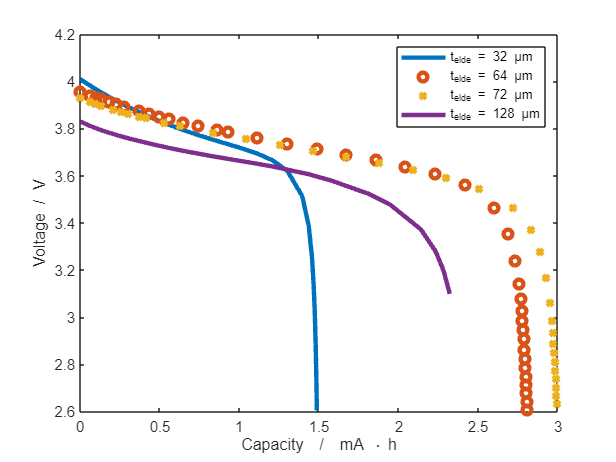

hold off
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')
legend( 't_{elde} = 32 µm', 't_{elde} = 64 µm','t_{elde} = 72 µm','t_{elde} = 128 µm')

#### **Example 5. Increasing the effective density of electrode coating**

The effective density of the electrode coating comprises both the active material and the pores. A crucial aspect of cell design is optimizing the ratio of pores to active material. While increasing the amount of active material enhances capacity and energy density by providing more lithium atoms, a less porous electrode reduces the electrolyte volume fraction. This reduction can impair the rate of ion transfer, leading to lower power densities and potential issues with the electrode’s mechanical stability. The density of the positive electrode, NMC is typically around 4650 kg/m³. To assess the impact of effective density on capacity, we vary it from 3500 to 4000 kg/m³. As discussed earlier, the electrolyte fills the pores between the electrode active particles. Therefore, increasing the effective density indefinitely is not possible, as it would reduce the electrolyte volume and hinder the transport of Li-ions. In the plot shown below, we observe that the calculation does not converge for an effective density of 4000 kg/m³. Additionally, we have plotted the carrier concentration in the electrolyte, revealing the depletion of ions within it.

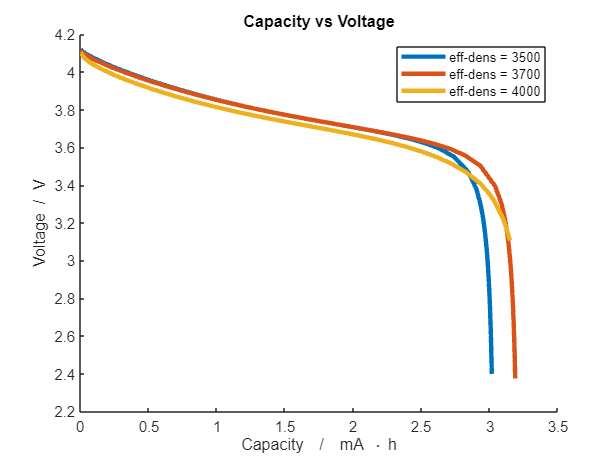

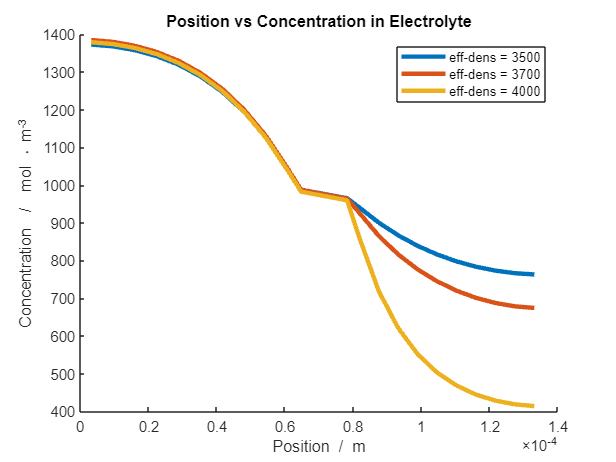

Solving timestep 01/45:                      -> 3 Seconds, 937 Milliseconds
Solving timestep 02/45: 3 Seconds, 937 Milliseconds -> 7 Seconds, 875 Milliseconds
Solving timestep 03/45: 7 Seconds, 875 Milliseconds -> 15 Seconds, 750 Milliseconds
Solving timestep 04/45: 15 Seconds, 750 Milliseconds -> 31 Seconds, 500 Milliseconds
Solving timestep 05/45: 31 Seconds, 500 Milliseconds -> 63 Seconds
Solving timestep 06/45: 63 Seconds           -> 126 Seconds
Solving timestep 07/45: 126 Seconds          -> 252 Seconds
Solving timestep 08/45: 252 Seconds          -> 378 Seconds
Solving timestep 09/45: 378 Seconds          -> 504 Seconds
Solving timestep 10/45: 504 Seconds          -> 630 Seconds
Solving timestep 11/45: 630 Seconds          -> 756 Seconds
Solving timestep 12/45: 756 Seconds          -> 882 Seconds
Solving timestep 13/45: 882 Seconds          -> 1008 Seconds
Solving timestep 14/45: 1008 Seconds         -> 1134 Seconds
Solving timestep 15/45: 1134 Seconds         -> 1260 Seconds
So

Solving timestep 01/45:                      -> 3 Seconds, 937 Milliseconds
Solving timestep 02/45: 3 Seconds, 937 Milliseconds -> 7 Seconds, 875 Milliseconds
Solving timestep 03/45: 7 Seconds, 875 Milliseconds -> 15 Seconds, 750 Milliseconds
Solving timestep 04/45: 15 Seconds, 750 Milliseconds -> 31 Seconds, 500 Milliseconds
Solving timestep 05/45: 31 Seconds, 500 Milliseconds -> 63 Seconds
Solving timestep 06/45: 63 Seconds           -> 126 Seconds
Solving timestep 07/45: 126 Seconds          -> 252 Seconds
Solving timestep 08/45: 252 Seconds          -> 378 Seconds
Solving timestep 09/45: 378 Seconds          -> 504 Seconds
Solving timestep 10/45: 504 Seconds          -> 630 Seconds
Solving timestep 11/45: 630 Seconds          -> 756 Seconds
Solving timestep 12/45: 756 Seconds          -> 882 Seconds
Solving timestep 13/45: 882 Seconds          -> 1008 Seconds
Solving timestep 14/45: 1008 Seconds         -> 1134 Seconds
Solving timestep 15/45: 1134 Seconds         -> 1260 Seconds
So

Solving timestep 01/45:                      -> 3 Seconds, 937 Milliseconds
Solving timestep 02/45: 3 Seconds, 937 Milliseconds -> 7 Seconds, 875 Milliseconds
Solving timestep 03/45: 7 Seconds, 875 Milliseconds -> 15 Seconds, 750 Milliseconds
Solving timestep 04/45: 15 Seconds, 750 Milliseconds -> 31 Seconds, 500 Milliseconds
Solving timestep 05/45: 31 Seconds, 500 Milliseconds -> 63 Seconds
Solving timestep 06/45: 63 Seconds           -> 126 Seconds
Solving timestep 07/45: 126 Seconds          -> 252 Seconds
Solving timestep 08/45: 252 Seconds          -> 378 Seconds
Solving timestep 09/45: 378 Seconds          -> 504 Seconds
Solving timestep 10/45: 504 Seconds          -> 630 Seconds
Solving timestep 11/45: 630 Seconds          -> 756 Seconds
Solving timestep 12/45: 756 Seconds          -> 882 Seconds
Solving timestep 13/45: 882 Seconds          -> 1008 Seconds
Solving timestep 14/45: 1008 Seconds         -> 1134 Seconds
Solving timestep 15/45: 1134 Seconds         -> 1260 Seconds
So

*** Simulation complete. Solved 45 control steps in 2 Seconds, 402 Milliseconds ***


jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');% parse the sample_input.json for default values.
effective_density = [3500,3700,4000];
markers={'-',"-",'-'};
% Create two figures
figure1 = figure; % For capacity vs voltage
figure2 = figure; % For x vs c
output_dens = cell(size(effective_density));
timestep=10;
% use a for-loop to iterate through the vector of effective density
for i = 1 : numel(effective_density)
    % Modify the value for the coating thickness for the positiv electrode
        jsonstruct.PositiveElectrode.Coating.effectiveDensity = effective_density(i);
    % run the simulation and store the results in the output cell array
    output_dens{i} = runBatteryJson(jsonstruct);
    % retrieve the states from the simulation result
    states = output_dens{i}.states;
    % extract the time and voltage quantities
    time = cellfun(@(state) state.time, states);
    voltage = cellfun(@(state) state.('Control').E, states);
    current = cellfun(@(state) state.('Control').I, states);
    % calculate the capacity
    capacity = time .* current;
    % plot capacity vs voltage
    % instantiate an empty figure
    figure(figure1)
    hold on
    plot((capacity/(hour*milli)), voltage, markers{i}, 'linewidth', 3);
    title('Capacity vs Voltage');
    xlabel('Capacity  /  mA \cdot h')
    ylabel('Voltage  /  V')
    legend( 'eff-dens = 3500', 'eff-dens = 3700','eff-dens = 4000');
    figure(figure2)
    hold on
    x = output_dens{i}.model.grid.cells.centroids;
    c = output_dens{i}.states{5}.Electrolyte.c;  %at timestep 5
    plot(x, c, 'LineWidth', 3);
    title('Position vs Concentration in Electrolyte');
    xlabel('Position  /  m')
    ylabel('Concentration  /  mol \cdot m^{-3}')
    legend( 'eff-dens = 3500', 'eff-dens = 3700','eff-dens = 4000');    
end

#### **Example 6. Influence of material chemistry on capacity**

Let's now replace the positive electrode material NMC 811 with LiFePO4 (LFP) [2]. Different positive electrode materials have varying lithium saturation concentrations, reaction rate constants, and densities. LFP has a lower density and a lower lithium ion saturation concentration compared to NMC 811. As a result, we expect to observe a lower capacity with LFP. Additionally, the shape of the discharge curve will differ, reflecting the distinct electrochemical behavior of LFP compared to NMC 811. 

positive_electrode_materials = ["NMC","LFP"];
markers={'-',"-",};
output_mat = cell(size(positive_electrode_materials));
% instantiate an empty figure
figure()
% use a for-loop to iterate through the vector of positive electrode materials
for i = 1:numel(positive_electrode_materials)
    % Parse the sample input JSON for default values, not the default
    % material used here is NMC
    jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
    if positive_electrode_materials(i) == "LFP"
        % Load the LFP json parameters
        lfp = parseBattmoJson('ParameterData/MaterialProperties/LFP/LFP.json');
        jsonstruct_lfp.PositiveElectrode.Coating.ActiveMaterial.Interface = lfp;
       jsonstruct = mergeJsonStructs({jsonstruct_lfp, jsonstruct});
       jsonstruct.PositiveElectrode.Coating.ActiveMaterial.density = jsonstruct.PositiveElectrode.Coating.ActiveMaterial.Interface.density;
       % the effective density also needs to be changed here for 
       % the new material
       jsonstruct.PositiveElectrode.Coating.effectiveDensity = 2709;
    end 
        % Run the simulation and store the results in the output cell array
        output_mat{i} = runBatteryJson(jsonstruct);        
        % Retrieve the states from the simulation result
        states = output_mat{i}.states;
        % Extract time and voltage quantities
        time = cellfun(@(state) state.time, states);
        voltage = cellfun(@(state) state.('Control').E, states);
        current = cellfun(@(state) state.('Control').I, states);
        % Calculate the capacity
        capacity = time .* current;
        % plot capacity vs voltage
        plot((capacity/(hour*milli)), voltage, markers{i}, 'linewidth', 3);
    hold on
end

Solving timestep 01/45:                      -> 3 Seconds, 937 Milliseconds
Solving timestep 02/45: 3 Seconds, 937 Milliseconds -> 7 Seconds, 875 Milliseconds
Solving timestep 03/45: 7 Seconds, 875 Milliseconds -> 15 Seconds, 750 Milliseconds
Solving timestep 04/45: 15 Seconds, 750 Milliseconds -> 31 Seconds, 500 Milliseconds
Solving timestep 05/45: 31 Seconds, 500 Milliseconds -> 63 Seconds
Solving timestep 06/45: 63 Seconds           -> 126 Seconds
Solving timestep 07/45: 126 Seconds          -> 252 Seconds
Solving timestep 08/45: 252 Seconds          -> 378 Seconds
Solving timestep 09/45: 378 Seconds          -> 504 Seconds
Solving timestep 10/45: 504 Seconds          -> 630 Seconds
Solving timestep 11/45: 630 Seconds          -> 756 Seconds
Solving timestep 12/45: 756 Seconds          -> 882 Seconds
Solving timestep 13/45: 882 Seconds          -> 1008 Seconds
Solving timestep 14/45: 1008 Seconds         -> 1134 Seconds
Solving timestep 15/45: 1134 Seconds         -> 1260 Seconds
So

parameter PositiveElectrode.Coating.ActiveMaterial.Interface.saturationConcentration is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.ActiveMaterial.Interface.volumetricSurfaceArea is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.ActiveMaterial.Interface.density is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.ActiveMaterial.Interface.activationEnergyOfReaction is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.ActiveMaterial.Interface.reactionRateConstant is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.ActiveMaterial.Interface.guestStoichiometry100 is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectr

Solving timestep 01/45:                      -> 3 Seconds, 937 Milliseconds
Solving timestep 02/45: 3 Seconds, 937 Milliseconds -> 7 Seconds, 875 Milliseconds
Solving timestep 03/45: 7 Seconds, 875 Milliseconds -> 15 Seconds, 750 Milliseconds
Solving timestep 04/45: 15 Seconds, 750 Milliseconds -> 31 Seconds, 500 Milliseconds
Solving timestep 05/45: 31 Seconds, 500 Milliseconds -> 63 Seconds
Solving timestep 06/45: 63 Seconds           -> 126 Seconds
Solving timestep 07/45: 126 Seconds          -> 252 Seconds
Solving timestep 08/45: 252 Seconds          -> 378 Seconds
Solving timestep 09/45: 378 Seconds          -> 504 Seconds
Solving timestep 10/45: 504 Seconds          -> 630 Seconds
Solving timestep 11/45: 630 Seconds          -> 756 Seconds
Solving timestep 12/45: 756 Seconds          -> 882 Seconds
Solving timestep 13/45: 882 Seconds          -> 1008 Seconds
Solving timestep 14/45: 1008 Seconds         -> 1134 Seconds
Solving timestep 15/45: 1134 Seconds         -> 1260 Seconds
So

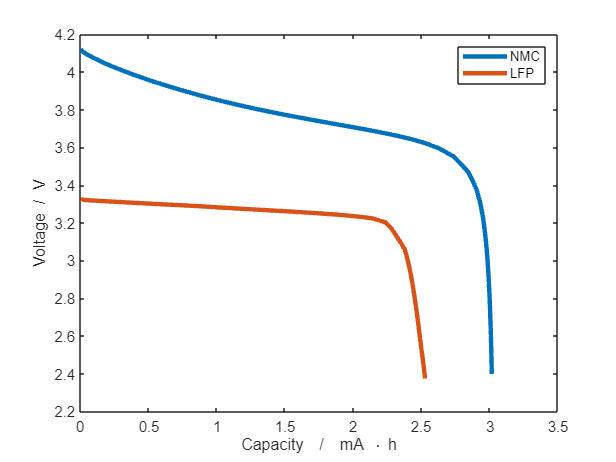

hold off
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')
legend( 'NMC', 'LFP')

As expected, we observe that the capacity of LiFePO4 (LFP) is lower compared to NMC, and the maximum open-circuit voltage (OCP) for the LFP-graphite system is also less than that of the NMC positive electrode. Additionally, the discharge curve for LFP is flatter, indicating that the voltage remains more constant throughout the discharge cycle compared to NMC.

**References**

[1] [Flores Cedeño, E. J. (2020). *Development of operando diagnostics for Li-ion positive electrodes by Raman spectroscopy* (Doctoral thesis, ETH Zurich).](https://doi.org/10.3929/ethz-b-000373382) 

[2] [Safari, M., et al. "Multimodal physics–based aging model for life prediction of Li–ion batteries." Journal of The Electrochemical Society 156.3 (2008): A145.](https://iopscience.iop.org/article/10.1149/1.3043429/meta)

[3] [Xu, Meng, et al. "A pseudo three–dimensional electrochemical–thermal model of a prismatic LiFePO4 battery during discharge process." Energy 80 (2015): 303–317.](https://www.sciencedirect.com/science/article/pii/S0360544214013437#sec2.6.1)

[4] [Karin Kleiner, Peter Jakes, Sebastian Scharner, Verena Liebau, Helmut Ehrenberg, "Changes of the balancing between negative electrode and positive electrode due to fatigue in commercial lithium-ion cells," *Journal of Power Sources*, Volume 317, 2016, Pages 25-34, ISSN 0378-7753, https://doi.org/10.1016/j.jpowsour.2016.03.049. ](https://www.sciencedirect.com/science/article/pii/S0378775316302506)

[5] [Z. Khalik, M.C.F. Donkers, H.J. Bergvel (2021). "Model simplifications and their impact on computational complexity for an electrochemistry-based battery modeling toolbox" *Journal of Power Sources*, 488, 229427](https://www.sciencedirect.com/science/article/pii/S0378775320317018?via%3Dihub#fig1). [https://doi.org/10.1016/j.jpowsour.2020.229427.](https://doi.org/10.1016/j.jpowsour.2020.229427.)

[6] [Z. Chen, D. L. Danilov, R.-A. Eichel, P. H. L. Notten, Porous Electrode Modeling and its Applications to Li-Ion Batteries. *Adv. Energy Mater.* 2022, 12, 2201506. https://doi.org/10.1002/aenm.202201506](https://onlinelibrary.wiley.com/doi/full/10.1002/aenm.202201506)

[7] [A. Sobkowiak, ‘LiFeSO4F as a Cathode Material for Lithium-Ion Batteries : Synthesis, Structure, and Function’, PhD dissertation, Acta Universitatis Upsaliensis, Uppsala, 2015.](https://uu.diva-portal.org/smash/record.jsf?pid=diva2%3A855021&dswid=3714)